# Robotics, Vision & Control 3e: for MATLAB

# Chapter 7: Robot Arm Kinematics 

close all      % close all existing figures
clear          % clear all workspace variables
format compact % compact printout  

## 7.1 Forward Kinematics

### 7.1.1 Forward Kinematics from a Pose Graph

#### 7.1.1.1 2-Dimensional (Planar) Robotic Arms

a1 = 1;
e = ETS2.Rz("q1")*ETS2.Tx(a1)

e = 
Rz(q1)Tx(1)


size(e)

ans =      1     2


e.fkine(pi/6)

ans =     0.8660   -0.5000    0.8660
    0.5000    0.8660    0.5000
         0         0    1.0000


se2(pi/6,"theta")*se2(eye(2),[a1 0])

ans = se2
    0.8660   -0.5000    0.8660
    0.5000    0.8660    0.5000
         0         0    1.0000

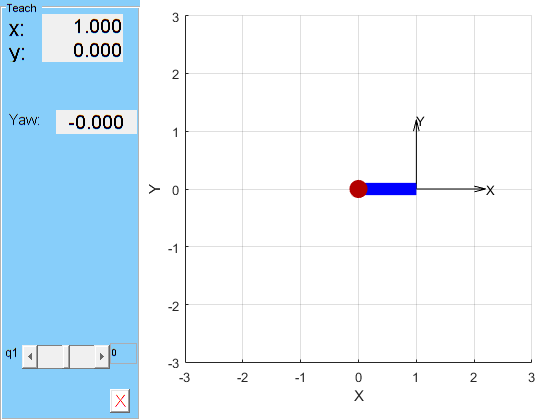

e.teach;

a1 = 1; a2 = 1;
e = ETS2.Rz("q1")*ETS2.Tx(a1)*ETS2.Rz("q2")*ETS2.Tx(a2)

e = 
Rz(q1)Tx(1)Rz(q2)Tx(1)


T = e.fkine(deg2rad([30 40]));
printtform2d(se2(T),unit="deg")

t = (1.21, 1.44), 70 deg


T = se2(deg2rad(30),"theta")*se2(eye(2),[a1 0]) * ...
  se2(deg2rad(40),"theta")*se2(eye(2),[a2 0]);
printtform2d(T,unit="deg")

       T: t = (1.21, 1.44), 70 deg


e.njoints

ans = 2

e.structure

ans = 'RR'

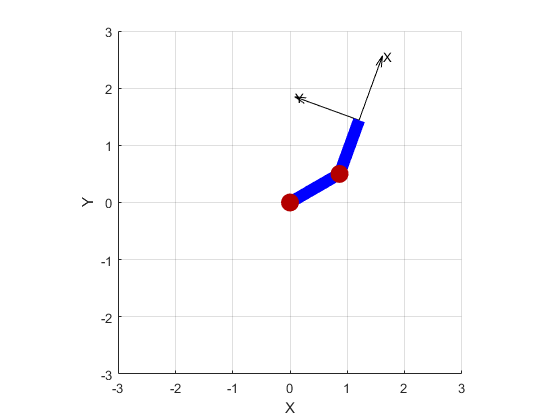

e.plot(deg2rad([30 40]));

etx = e(2)

etx = 
Tx(1)


etx.param

ans = 1

etx.T

ans =      1     0     1
     0     1     0
     0     0     1


e = ETS2.Rz("q1")*ETS2.Tx("q2",qlim=[1 2])

e = 
Rz(q1)Tx(q2)


e.structure

ans = 'RP'

#### 7.1.1.2 3-Dimensional Robotic Arms

a1 = 1; a2 = 1;
e = ETS3.Rz("q1")*ETS3.Ry("q2")* ...
  ETS3.Tz(a1)*ETS3.Ry("q3")*ETS3.Tz(a2)* ...
  ETS3.Rz("q4")*ETS3.Ry("q5")*ETS3.Rz("q6");
e.njoints

ans = 6

e.structure

ans = 'RRRRRR'

e.fkine(zeros(1,6))

ans =      1     0     0     0
     0     1     0     0
     0     0     1     2
     0     0     0     1


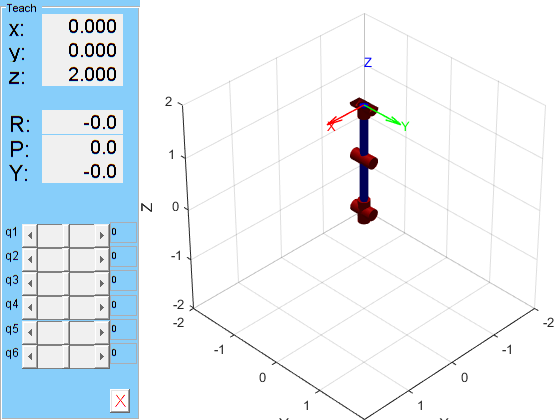

e.teach;

### 7.1.2 Forward Kinematics as a Chain of Robot Links

#### 7.1.2.2 2-Dimensional (Planar) Case

link1 = rigidBody("link1");
link1.Joint = rigidBodyJoint("joint1","revolute");
link2 = rigidBody("link2");
link2.Joint = rigidBodyJoint("joint2","revolute");
link2.Joint.setFixedTransform(se3([a1 0 0],"trvec"));
link3 = rigidBody("link3");
link3.Joint.setFixedTransform(se3([a2 0 0],"trvec"));
myRobot = rigidBodyTree(DataFormat="row");
myRobot.addBody(link1,myRobot.BaseName);
myRobot.addBody(link2,link1.Name);
myRobot.addBody(link3,link2.Name);
myRobot.homeConfiguration

ans =      0     0


myRobot.showdetails

--------------------
Robot: (3 bodies)

 Idx    Body Name       Joint Name       Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------       ----------       ----------    ----------------   ----------------
   1        link1           joint1         revolute             base(0)   link2(2)  
   2        link2           joint2         revolute            link1(1)   link3(3)  
   3        link3        link3_jnt            fixed            link2(2)   
--------------------


T = myRobot.getTransform(deg2rad([30 40]),"link3");
printtform(T,unit="deg")

       T: t = (1.21, 1.44, 0), RPY/zyx = (70, 0, 0) deg


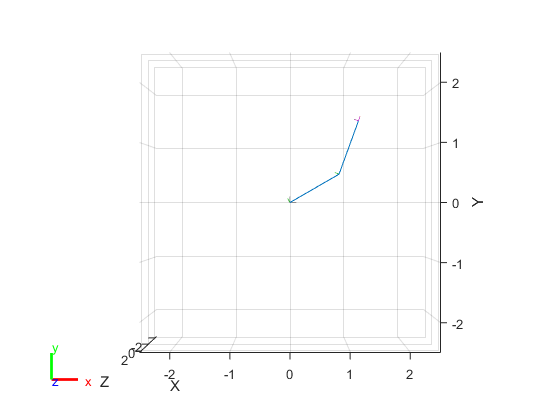

figure; % Create new figure
myRobot.show(deg2rad([30 40]));
view(0,90)   % show only XY (2D) plane

q = [linspace(0,pi,100)' linspace(0,-2*pi,100)'];
whos q

  Name        Size            Bytes  Class     Attributes

  q         100x2              1600  double              



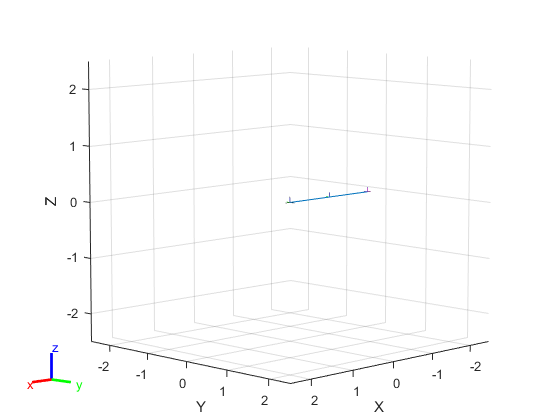

r = rateControl(10);
for i = 1:size(q,1)
  myRobot.show(q(i,:),FastUpdate=true,PreservePlot=false);
  r.waitfor;
end

link2 = myRobot.Bodies{2}

link2 =   rigidBody with properties:

            Name: 'link2'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
          Parent: [1×1 rigidBody]
        Children: {[1×1 rigidBody]}
         Visuals: {}
      Collisions: {}

link2 = myRobot.getBody("link2");
parentLink = link2.Parent;
childLinks = link2.Children;
link2.Joint.Type

ans = 'revolute'

link2.Joint.PositionLimits

ans =    -3.1416    3.1416


myRobot.getTransform(deg2rad([0 30]),"link2","link1")

ans =     0.8660   -0.5000         0    1.0000
    0.5000    0.8660         0         0
         0         0    1.0000         0
         0         0         0    1.0000


#### 7.1.2.3 3-Dimensional Case

a1 = 1; a2 = 1;
robot6 = ets2rbt(ETS3.Rz("q1")*ETS3.Ry("q2")* ...
  ETS3.Tz(a1)*ETS3.Ry("q3")*ETS3.Tz(a2)* ...
  ETS3.Rz("q4")*ETS3.Ry("q5")*ETS3.Rz("q6"));
robot6.homeConfiguration

ans =      0     0     0     0     0     0


%loadrobot("<TAB>
panda = loadrobot("frankaEmikaPanda",DataFormat="row");
panda.showdetails

--------------------
Robot: (11 bodies)

 Idx                Body Name                 Joint Name                 Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                 ----------                 ----------                ----------------   ----------------
   1              panda_link1               panda_joint1                   revolute                  panda_link0(0)   panda_link2(2)  
   2              panda_link2               panda_joint2                   revolute                  panda_link1(1)   panda_link3(3)  
   3              panda_link3               panda_joint3                   revolute                  panda_link2(2)   panda_link4(4)  
   4              panda_link4               panda_joint4                   revolute                  panda_link3(3)   panda_link5(5)  
   5              panda_link5               panda_joint5                   revolute                  panda_link4(4)   panda_link6(6)  
   6          

qr = [0 -0.3 0 -2.2 0 2 0.7854 0 0];
T = panda.getTransform(qr,"panda_hand");
printtform(T,unit="deg")

       T: t = (0.474, -4.18e-12, 0.516), RPY/zyx = (-0.000106, -5.73, -180) deg


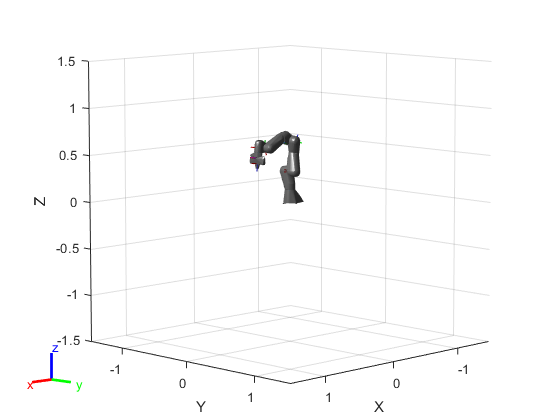

figure; % Create new figure
panda.show(qr);

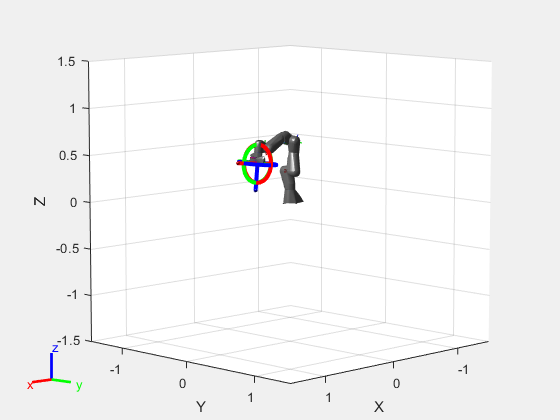

intPanda = interactiveRigidBodyTree(panda,Configuration=qr);

intPanda.Configuration'  % transpose for display

ans =          0   -0.3000         0   -2.2000         0    2.0000    0.7854         0         0


intPanda.addConfiguration;      % store configuration
intPanda.StoredConfigurations;  % retrieve stored trajectory

### 7.1.3 Branched Robots

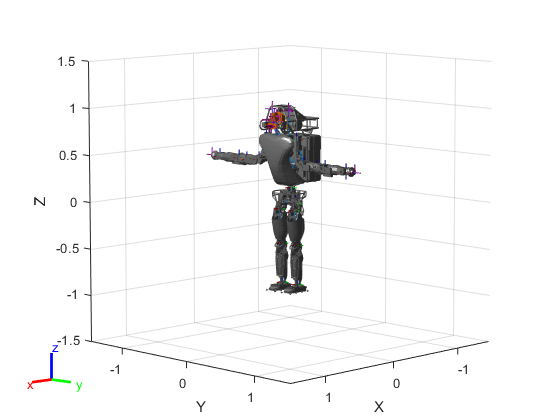

atlas = loadrobot("atlas",DataFormat="row");
figure; % Create new figure
atlas.show;

childLinks = atlas.getBody("utorso").Children';
size(childLinks)

ans =      5     1


cellfun(@(c) string(c.Name),childLinks)

ans = 5×1 string array
    "l_clav"
    "l_situational_awareness_camera_link"
    "head"
    "r_clav"
    "r_situational_awareness_camera_link"

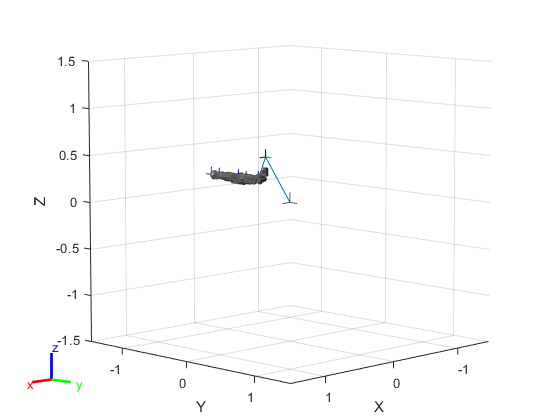

rightArm = atlas.subtree("r_clav");
rightArm.show;

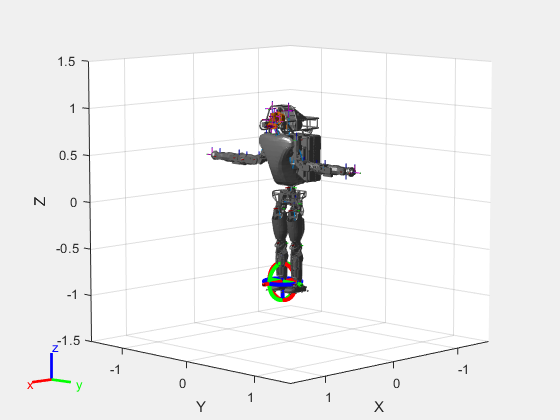

intAtlas = interactiveRigidBodyTree(atlas);

atlas.getTransform(atlas.homeConfiguration,"l_foot");
T = atlas.getTransform(atlas.homeConfiguration,"r_hand_force_torque","r_clav");
printtform(T,unit="deg")

       T: t = (0, -0.84, -0.261), RPY/zyx = (180, 0, 0) deg


### 7.1.4 Unified Robot Description Format (URDF)

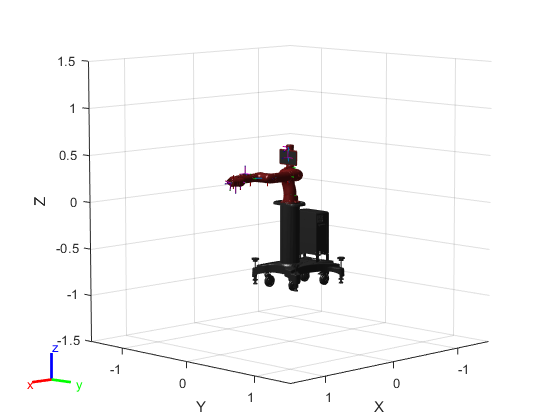

sawyer = importrobot("sawyer.urdf");
figure; % Create new figure
sawyer.show;

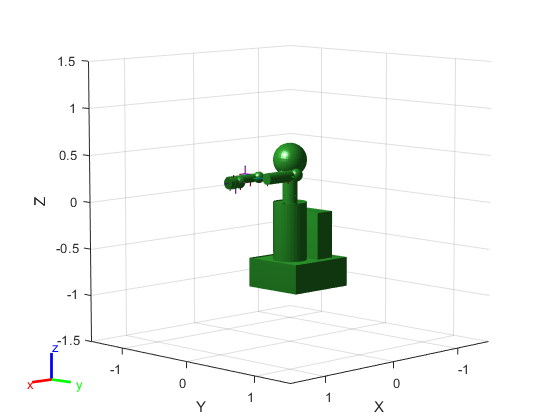

figure; % Create new figure for collision meshes
sawyer.show(Visuals="off",Collisions="on");

sawyer.getBody("head")

ans =   rigidBody with properties:

            Name: 'head'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1.5795
    CenterOfMass: [0.0053 -2.6549e-05 0.1021]
         Inertia: [0.0283 0.0248 0.0050 4.7027e-06 -8.0863e-04 -4.2438e-06]
          Parent: [1×1 rigidBody]
        Children: {[1×1 rigidBody]  [1×1 rigidBody]}
         Visuals: {'Mesh:head.stl'}
      Collisions: {'Sphere Radius 0.18'}

### 7.1.5 Denavit-Hartenberg Parameters

a = 1; alpha = 0; d = 0; theta = 0;
link = rigidBody("link1");
link.Joint = rigidBodyJoint("joint1","revolute");
link.Joint.setFixedTransform([a alpha d theta],"dh");

## 7.2 Inverse Kinematics

### 7.2.1 2-Dimensional (Planar) Robotic Arms

#### 7.2.1.1 Closed-Form Solution

syms a1 a2 real
e = ETS2.Rz("q1")*ETS2.Tx(a1)*ETS2.Rz("q2")*ETS2.Tx(a2);
syms q1 q2 real
TE = e.fkine([q1 q2])

$$TE = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

transl = TE(1:2,3)';
syms x y real
e1 = x == transl(1)

$$e1 = x=a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)$$

e2 = y == transl(2)

$$e2 = y=a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)$$

[s1,s2] = solve([e1 e2],[q1 q2]);

length(s2)

ans = 2

subs(s2(2),[a1 a2],[1 1])

$$ans = 2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)$$

xfk = eval(subs(transl(1), [a1 a2 q1 q2], ...
  [1 1 deg2rad(30) deg2rad(40)]))

xfk = 1.2080

yfk = eval(subs(transl(2), [a1 a2 q1 q2], ...
  [1 1 deg2rad(30) deg2rad(40)]))

yfk = 1.4397

q1r = eval(subs(s1(2),[a1 a2 x y],[1 1 xfk yfk]));
q1 = rad2deg(q1r)

q1 = 30.0000

q2r = eval(subs(s2(2),[a1 a2 x y],[1 1 xfk yfk]));
q2 = rad2deg(q2r)

q2 = 40.0000

#### 7.2.1.2 Numerical Solution

e = ETS2.Rz("q1")*ETS2.Tx(1)*ETS2.Rz("q2")*ETS2.Tx(1);
pstar = [0.6 0.7];  % Desired position
q = fminsearch(@(q) norm(se2(e.fkine(q)).trvec-pstar),[0 0])

q =    -0.2295    2.1833


printtform2d(e.fkine(q),unit="deg")

t = (0.6, 0.7), 112 deg


### 7.2.2 3-Dimensional Robotic Arms

#### 7.2.2.1 Closed-Form Solution

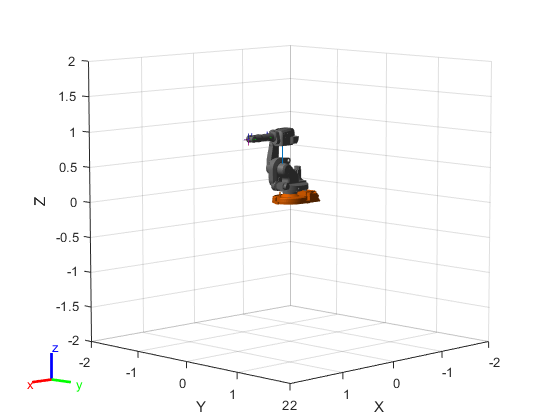

abb = loadrobot("abbIrb1600",DataFormat="row");
figure % Create new figure for robot
abb.show;

abb.showdetails

--------------------
Robot: (7 bodies)

 Idx     Body Name           Joint Name           Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------           ----------           ----------     ----------------   ----------------
   1        link_1              joint_1             revolute         base_link(0)   link_2(2)  
   2        link_2              joint_2             revolute            link_1(1)   link_3(3)  
   3        link_3              joint_3             revolute            link_2(2)   link_4(4)  
   4        link_4              joint_4             revolute            link_3(3)   link_5(5)  
   5        link_5              joint_5             revolute            link_4(4)   link_6(6)  
   6        link_6              joint_6             revolute            link_5(5)   tool0(7)  
   7         tool0        joint_6-tool0                fixed            link_6(6)   
--------------------


aIK = analyticalInverseKinematics(abb);
aIK.showdetails

--------------------
Robot: (7 bodies)

Index      Base Name   EE Body Name     Type                    Actions
-----      ---------   ------------     ----                    -------
    1      base_link         link_6   RRRSSS   Use this kinematic group
    2      base_link          tool0   RRRSSS   

abb.getBody("tool0").Joint.Type

ans = 'fixed'

T = abb.getBody("tool0").Joint.JointToParentTransform;
printtform(T)

       T: t = (0, 0, 0), RPY/zyx = (0, 1.57, 0) rad


abbIKFcn = aIK.generateIKFunction("ikIRB1600")

abbIKFcn = function_handle with value:
    @ikIRB1600

% To find 2 possible target configurations
tgtPose = trvec2tform([0.93 0 0.5])*eul2tform([0 pi/2 0]);
qsol = abbIKFcn(tgtPose)

qsol =     0.0000    0.5695    0.1306    3.1416    0.7000    3.1416
    0.0000    0.5695    0.1306         0   -0.7000    0.0000


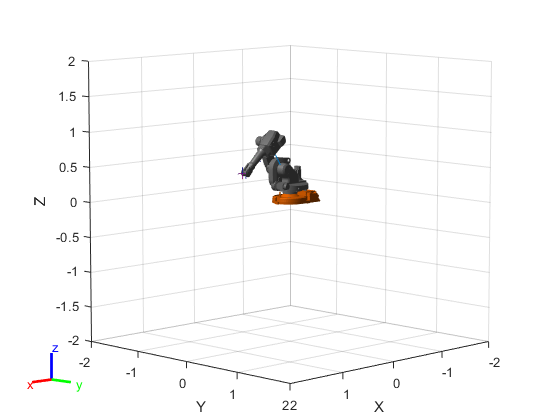

qn = qsol(1,:);
abb.show(qn);

T1 = abb.getTransform(qsol(1,:),"tool0");
printtform(T1)

      T1: t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


T2 = abb.getTransform(qsol(2,:),"tool0");
printtform(T2)

      T2: t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


% To find all possible target configurations, disable joint limits
% Interesting configurations: 2, 3, 4, 6
qsol = abbIKFcn(tgtPose,false)

qsol =     0.0000    2.5344    3.0110    0.0000    0.7378    0.0000
   -3.1416    4.3471   -0.8952    3.1416    0.3103    0.0000
    0.0000    0.5695    0.1306    3.1416    0.7000    3.1416
   -3.1416   -1.1789   -2.2464    0.0000    0.2837    3.1416
   -3.1416    4.3471    5.3880    3.1416    0.3103    0.0000
    0.0000    2.5344    3.0110    3.1416   -0.7378    3.1416
   -3.1416    4.3471   -0.8952   -0.0000   -0.3103    3.1416
    0.0000    0.5695    0.1306         0   -0.7000    0.0000
   -3.1416   -1.1789   -2.2464   -3.1416   -0.2837   -0.0000
   -0.0000    2.5344   -3.2722   -3.1416   -0.7378    3.1416


abbIKFcn(trvec2tform([3,0,0]))

ans =
  0×6 empty double matrix


q = [0 pi/4 0 0.1 0 0.4];
qsol = abbIKFcn(abb.getTransform(q,"tool0"))

qsol =     0.0000    0.7854    0.0000   -0.5354         0    1.0354


pr2 = loadrobot("willowgaragePR2",DataFormat="row");
aIK2 = analyticalInverseKinematics(pr2);
aIK2.showdetails

--------------------
Robot: (94 bodies)

Index                                          Base Name                                       EE Body Name     Type                    Actions
-----                                          ---------                                       ------------     ----                    -------
    1                                l_shoulder_pan_link                                  l_wrist_roll_link   RSSSSS   Use this kinematic group
    2                                r_shoulder_pan_link                                  r_wrist_roll_link   RSSSSS   

% openExample("robotics/SolveAnalyticalIKForLargeDOFRobotExample")

#### 7.2.2.2 Numerical Solution

abbHome = abb.homeConfiguration;
T = abb.getTransform(qn,"tool0");
printtform(T)

       T: t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


abbIK = inverseKinematics(RigidBodyTree=abb);
[qsol,solinfo] = abbIK("tool0",T,ones(1,6),abbHome)

qsol =    -0.0000    0.5695    0.1306    0.0000   -0.7000    0.0000


solinfo = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6805e-09
             ExitFlag: 1
               Status: 'success'

qn

qn =     0.0000    0.5695    0.1306    3.1416    0.7000    3.1416


T2 = abb.getTransform(qsol,"tool0");
printtform(T2)

      T2: t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


qsol = abbIK("tool0",T,ones(1,6),[0 0 0 pi 0 0])

qsol =    -0.0000    0.5695    0.1306    3.1416    0.7000    3.1416


tNumericalIK = timeit(@() abbIK("tool0",T,ones(1,6),abbHome))

tNumericalIK = 0.0080

tAnalyticalIK = timeit(@() abbIKFcn(T))

tAnalyticalIK = 0.0011

tNumericalIK / tAnalyticalIK

ans = 7.3966

### 7.2.3 Underactuated Manipulator

cobra = loadrvcrobot("cobra");
TE = se3(deg2rad([170 0 30]),"eul","XYZ",[0.4 -0.3 0.2]);
cobraHome = cobra.homeConfiguration;
cobraIK = inverseKinematics(RigidBodyTree=cobra);
weights = ones(1,6); 
rng(0); % obtain repeatable results
[qsol,solinfo] = cobraIK("link4",TE.tform,weights,cobraHome)

qsol =    -1.1760    1.1760    0.1870    0.5236


solinfo = struct with fields:
           Iterations: 1500
    NumRandomRestarts: 86
        PoseErrorNorm: 0.1745
             ExitFlag: 2
               Status: 'best available'

weights = [0 0 1 1 1 1];
[qsol,solinfo] = cobraIK("link4",TE.tform,weights,cobraHome)

qsol =    -0.1110   -1.1760    0.1870   -0.7634


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0509e-08
             ExitFlag: 1
               Status: 'success'

T4 = cobra.getTransform(qsol,"link4");
printtform(T4,unit="deg",mode="xyz")

      T4: t = (0.4, -0.3, 0.2), RPY/xyz = (180, 0, 30) deg


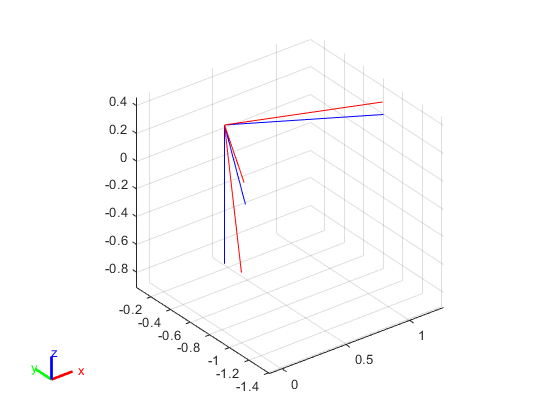

plotTransforms(TE,FrameColor="red"); hold on
plotTransforms(se3(T4),FrameColor="blue")

### 7.2.4 Overactuated (Redundant) Manipulator

panda = loadrobot("frankaEmikaPanda",DataFormat="row");
TE = se3(trvec2tform([0.7 0.2 0.1]))* ...
  se3(oa2tform([0 1 0],[0 0 -1]));
pandaHome = panda.homeConfiguration;
pandaIK = inverseKinematics(RigidBodyTree=panda); 
rng(0); % obtain repeatable results
qsol = pandaIK("panda_hand",TE.tform,ones(1,6),pandaHome)

qsol =     1.0166    1.5964   -1.2999   -1.2547    1.5099    1.8361   -2.5897         0         0


handT = panda.getTransform(qsol,"panda_hand");
printtform(handT,mode="axang",unit="deg")

   handT: t = (0.7, 0.2, 0.1),  R = (180deg | 1.49e-09, -1, -6.45e-09)


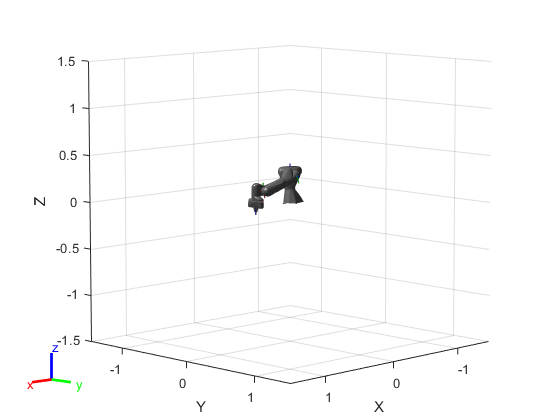

figure; % Create new figure
panda.show(qsol);

## 7.3 Trajectories

### 7.3.1 Joint-Space Motion

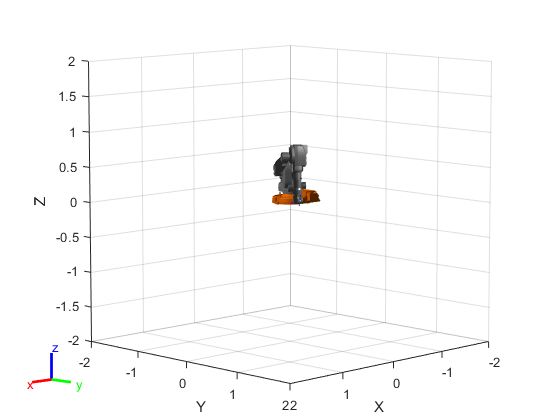

TE1 = se3(3,"rotx",[0.6 -0.5 0.1]);
TE2 = se3(2,"rotx",[0.4 0.5 0.1]);
sol1 = abbIKFcn(TE1.tform);
sol2 = abbIKFcn(TE2.tform);
waypts = [sol1(1,:)' sol2(1,:)'];
t = 0:0.02:2;
[q,qd,qdd] = quinticpolytraj(waypts,[0 2],t);
[q,qd,qdd] = trapveltraj(waypts,numel(t),EndTime=2);
r = rateControl(50);
for i = 1:size(q,2)
  abb.show(q(:,i)',FastUpdate=true,PreservePlot=false);
  r.waitfor;
end

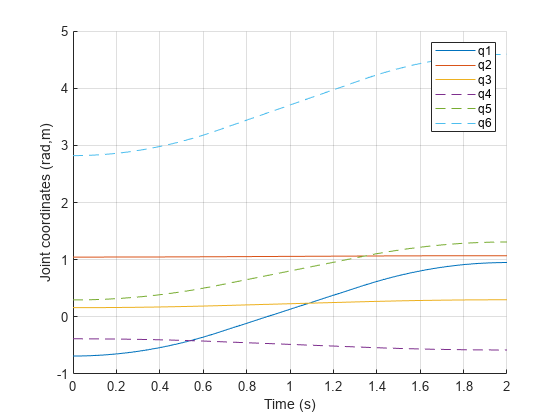

figure; % Create figure for joint plots
xplot(t,q')

for i = 1:size(q,2)
  trajT(i) = se3(abb.getTransform(q(:,i)',"tool0"));
end
size(trajT)

ans =      1   101


p = trajT.trvec;
size(p)

ans =    101     3


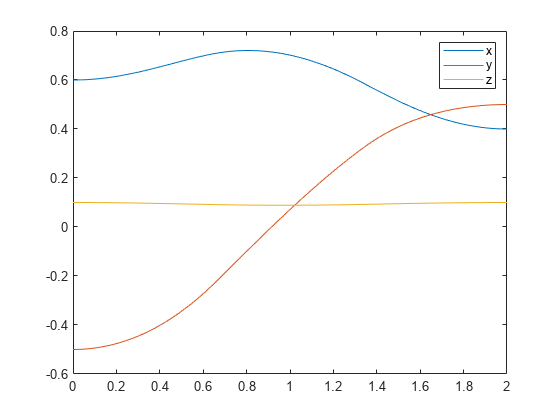

figure; % Create figure
plot(t,p);
legend("x","y","z")

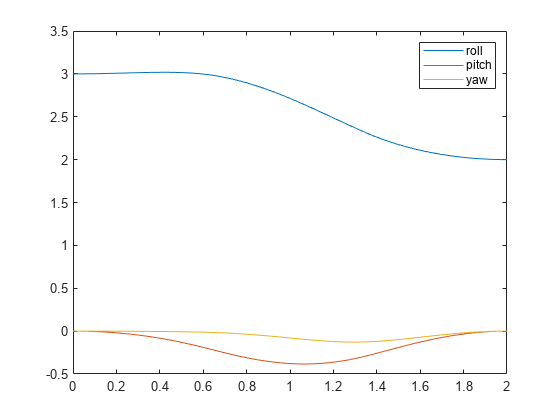

figure; % Create figure
plot(t,trajT.eul("XYZ"))
legend("roll","pitch","yaw")

### 7.3.2 Cartesian Motion

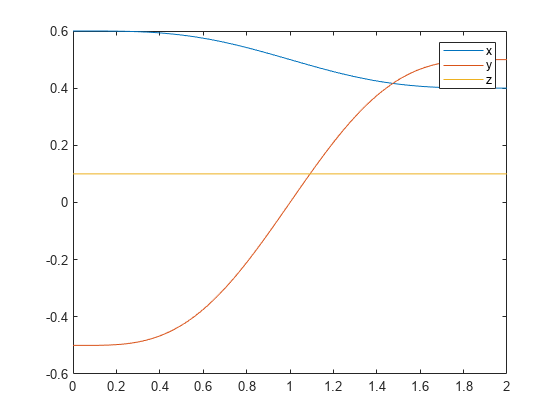

T = transformtraj(TE1,TE2,[0 2],t);
[s,sd,sdd] = minjerkpolytraj([0 1],[0 2],numel(t));
Ts = transformtraj(TE1,TE2,[0 2],t, ...
  TimeScaling=[s;sd;sdd]);
figure;
plot(t,Ts.trvec);
legend("x","y","z")

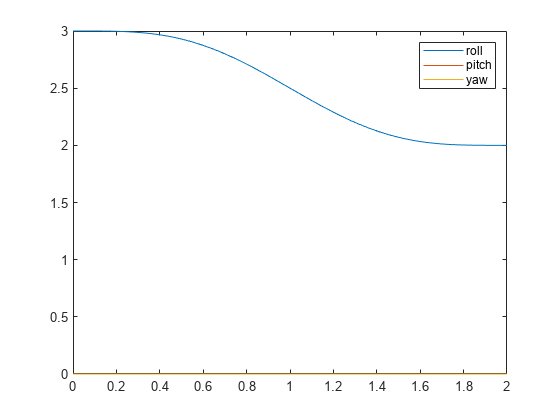

figure;
plot(t,Ts.eul("XYZ"));
legend("roll","pitch","yaw")

qj = ikineTraj(abbIKFcn,Ts);
% openExample("robotics/" + ...
%  "ChooseATrajectoryForAManipulatorApplicationExample");

### 7.3.3 Kinematics in Simulink

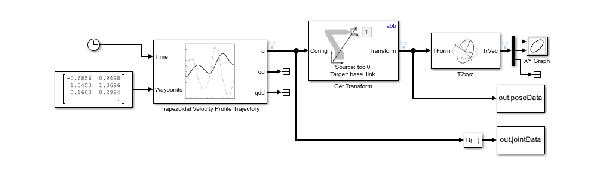

sl_jointspace
figure;
snapshotModel("sl_jointspace")

### 7.3.4 Motion Through a Singularity

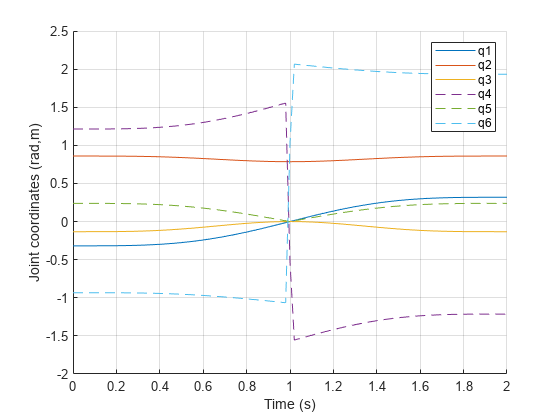

qsing = [0 pi/4 0 0.1 0 0.4];
TG = se3(abb.getTransform(qsing,"tool0"));
TE1 = se3(trvec2tform([0 -0.3 0]))*TG;
TE2 = se3(trvec2tform([0 0.3 0]))*TG;
Ts = transformtraj(TE1,TE2,[0 2],t, ...
  TimeScaling=[s;sd;sdd]);
qj = ikineTraj(abbIKFcn,Ts);
figure;
xplot(t,qj,unwrap=true)

qj_num = ikineTrajNum(abb,Ts);
m = manipulability(abb,qj);

## 7.4 Applications

### 7.4.1 Writing on a Surface

load hershey
B = hershey{'B'}

B = struct with fields:
    stroke: [2×23 double]
     width: 0.8400
       top: 0.8400
    bottom: 0

B.stroke

ans =     0.1600    0.1600       NaN    0.1600    0.5200    0.6400    0.6800    0.7200    0.7200    0.6800    0.6400    0.5200       NaN    0.1600    0.5200    0.6400    0.6800    0.7200    0.7200    0.6800    0.6400    0.5200    0.1600
    0.8400         0       NaN    0.8400    0.8400    0.8000    0.7600    0.6800    0.6000    0.5200    0.4800    0.4400       NaN    0.4400    0.4400    0.4000    0.3600    0.2800    0.1600    0.0800    0.0400         0         0


p = [0.5*B.stroke; zeros(1,size(B.stroke,2))];
k = find(isnan(p(1,:)));
p(:,k) = p(:,k-1); p(3,k) = 0.2;
dt = 0.02;  % sample interval
traj = mstraj(p(:,2:end)',[0.5 0.5 0.5],[],p(:,1)',dt,0.2);
whos traj

  Name        Size            Bytes  Class     Attributes

  traj      558x3             13392  double              



size(traj,1)*dt

ans = 11.1600

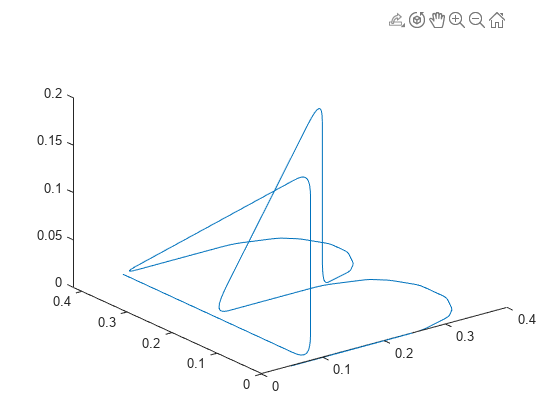

plot3(traj(:,1),traj(:,2),traj(:,3))

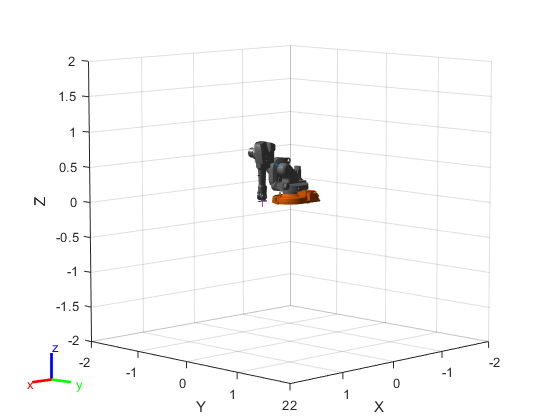

Tp = se3(trvec2tform([0.5 0 0.075]))*se3(eye(3),traj)* ...
  se3(oa2tform([0 1 0],[0 0 -1]));
qj = ikineTraj(abbIKFcn,Tp);
figure;
r = rateControl(1/dt);
for i = 1:size(qj,1)
  abb.show(qj(i,:),FastUpdate=true,PreservePlot=false);
  r.waitfor;
end

### 7.4.2 A 4-Legged Walking Robot

L1 = 0.5;
L2 = 0.5;
e = ETS3.Rz("q1")*ETS3.Rx("q2")*ETS3.Ty(-L1)* ...
  ETS3.Rx("q3")*ETS3.Tz(-L2);
leg = ets2rbt(e);
se3(leg.getTransform([0 0 0],"link5")).trvec

ans =          0   -0.5000   -0.5000


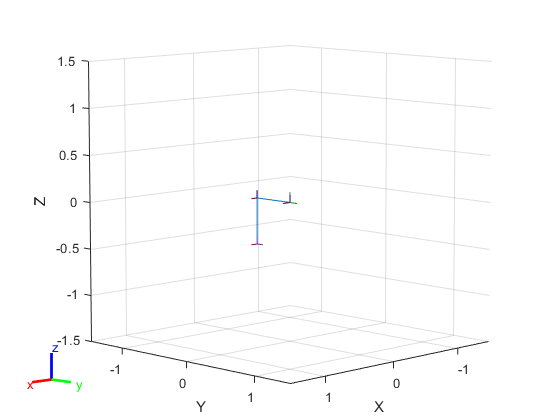

figure;
leg.show;

#### 7.4.2.1 Motion of One Leg

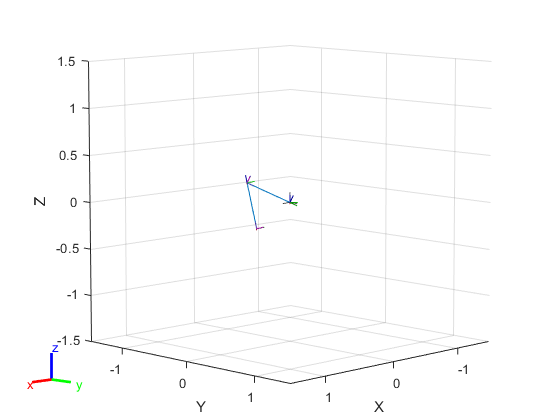

xf = 0.25; xb = -xf;  y = -0.25; zu = -0.1; zd = -0.25;
via = [xf y zd
       xb y zd
       xb y zu
       xf y zu
       xf y zd];
x = mstraj(via,[],[3 0.25 0.5 0.25],[],0.01,0.1);
qcycle = ikineTrajNum(leg,se3(eye(3),x),"link5", ...
  weights=[0 0 0 1 1 1]);
r = rateControl(50);
for i = 1:size(qcycle,1)
  leg.show(qcycle(i,:),FastUpdate=true,PreservePlot=false);
  r.waitfor;
end

#### 7.4.2.2 Motion of Four Legs

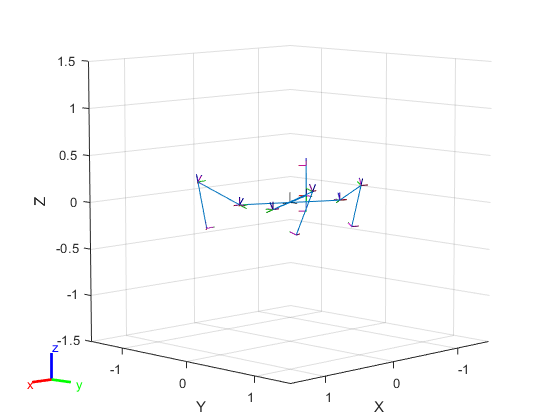

W = 0.5; L = 1;
Tflip = se3(pi,"rotz");
legs = [ ...
  rbtTform(leg,se3(eye(3),[L/2 W/2 0])*Tflip), ...
  rbtTform(leg,se3(eye(3),[-L/2 W/2 0])*Tflip), ...
  rbtTform(leg,se3(eye(3),[L/2 -W/2 0])), ...
  rbtTform(leg,se3(eye(3),[-L/2 -W/2 0]))];
r = rateControl(50);
for i = 1:500
  legs(1).show(gait(qcycle,i,0,false)); hold on;
  legs(2).show(gait(qcycle,i,100,false));
  legs(3).show(gait(qcycle,i,200,true));
  legs(4).show(gait(qcycle,i,300,true)); hold off;
  r.waitfor;
end

% This function is shown in the book section, but it is not executable here.
%function q = gait(cycle, k, phi, flip)
%  k = mod(k+phi-1,size(cycle,1))+1;
%  q = cycle(k,:);
%  if flip
%    q(1) = -q(1);   % for left-side legs
% end

## 7.5 Advanced Topics

### 7.5.1 Creating the Kinematic Model for a Robot

L1 = 0.672; L2 = -0.2337; L3 = 0.4318;
L4 = 0.0203; L5 = 0.0837; L6 = 0.4318;
e = ETS3.Tz(L1)*ETS3.Rz("q1")*ETS3.Ty(L2)*ETS3.Ry("q2") ...
   *ETS3.Tz(L3)*ETS3.Tx(L4)*ETS3.Ty(L5)*ETS3.Ry("q3") ...
   *ETS3.Tz(L6)*ETS3.Rz("q4")*ETS3.Ry("q5")*ETS3.Rz("q6");
robot = ets2rbt(e);

### 7.5.2 Modified Denavit-Hartenberg Parameters

a = 1; alpha = 0; d = 0; theta = 0;
link = rigidBody("link1");
link.Joint = rigidBodyJoint("joint1","revolute");
link.Joint.setFixedTransform([a alpha d theta],"mdh");

### 7.5.3 Products of Exponentials

a1 = 1; a2 = 1;
TE0 = se2(eye(2),[a1+a2 0]);
S0 = Twist2d.UnitRevolute([0 0]);
S1 = Twist2d.UnitRevolute([a1 0]);
TE = S0.exp(deg2rad(30))*S1.exp(deg2rad(40))*TE0

TE = se2
    0.3420   -0.9397    1.2080
    0.9397    0.3420    1.4397
         0         0    1.0000


### 7.5.4 Collision Checking

panda = loadrobot("frankaEmikaPanda",DataFormat="row");
qp = [0 -0.3 0 -2.2 0 2 0.7854 0, 0];
figure;
panda.show(qp,Visuals="off",Collisions="on",Frames="off");
box = collisionBox(1,1,1);
box.Pose = se3([1.1 -0.5 0],"trvec");
panda.checkCollision(qp,{box},IgnoreSelfCollision="on")

ans = logical
   0

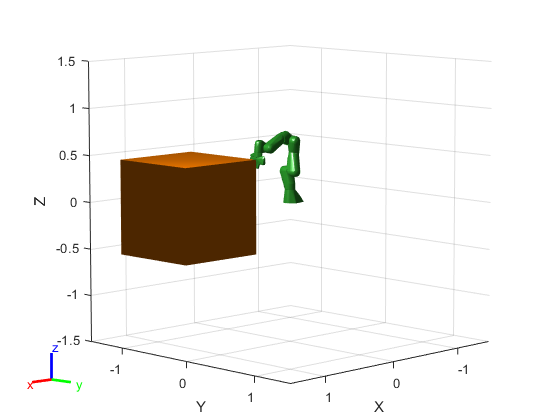

box.Pose = se3([1.0 -0.5 0],"trvec");
hold on; box.show

panda.checkCollision(qp,{box},IgnoreSelfCollision="on")

ans = logical
   1

vehicleMesh = stlread("groundvehicle.stl");
vehicle = collisionMesh(vehicleMesh.Points/100);
vehicle.Pose = se3([0.5 0 0],"trvec");
[isColl,sepDist,witPts] = panda.checkCollision(qp,{vehicle}, ...
   IgnoreSelfCollision="on")

isColl = logical
   0

sepDist =     0.3448
    0.3733
    0.5390
    0.5474
    0.3767
    0.3717
    0.3162
       Inf
    0.2506
    0.2042


witPts =     0.0552    0.4000
   -0.0036   -0.0036
    0.1410    0.1410
    0.0521    0.4000
    0.0640    0.0640
    0.3154    0.1800
   -0.0052    0.4000
   -0.0078   -0.0078
    0.5355    0.1800
    0.1117    0.4000
